GFDM parameters

Plot = true;

addpath(genpath('SEM'));

gfdm = struct;
gfdm.K = 8; % Subcarriers
gfdm.M = 7; % Subsymbols

gfdm.K_set = [7,0,1]; % Used subcarrier index(0 based)
gfdm.M_set = (1:6);       % Used subsymbol index(0 based). 1 guard subsymbol.

gfdm.CP = 0;    % CP length

% BW = 100; % Mhz

gfdm = GFDM_init(gfdm);

D = gfdm.D;
D_prime = gfdm.D_prime;

Es = 1;

delta_f = 10^-2;     % Normalized frequency: f = F/B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);

Problem & Dottorro iterative algorithm


$$\mathbf{S}=\mathrm{vec}(\mathbf{G})\mathrm{vec}(\mathbf{G})^H$$


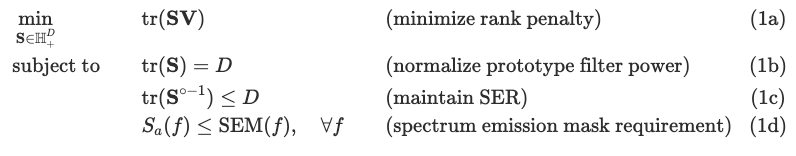

s_2 = 1;
w = 0.0003;
V_tilde = zeros(D);

% Interpolation filter
P = rc_filter(delta_f, f_range, 0.1);

counter = 1;
while abs(s_2) > 10^-6
    tic
    cvx_begin sdp %quiet
    variable S(D, D) hermitian nonnegative semidefinite
    % variable B nonnegative
    expression psd_temp(length(P), 1)
    
    % SEM
    mask = db2pow(ac(delta_f, f_range, 100));
    % SEM = dcp_SEM(delta_f, f_range, B);
    
    psd = (P.^2) .* PSD_S_vecG(S, f_range, psd_temp, gfdm.K, gfdm.M, gfdm.K_set, gfdm.M_set, gfdm.CP, delta_f, Es);
    
    minimize trace(S * V_tilde) %a
    subject to
    trace(S) == D; %b
    sum(inv_pos(diag(S))) <= D; %c
    psd <= mask;  %d
    
    cvx_end
    toc

 
Calling SDPT3 4.0: 6543 variables, 3192 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 3192
 dim. of sdp    var  = 336,   num. of sdp  blk  = 58
 dim. of linear var  = 102
 dim. of free   var  =  1 *** convert ublk to lblk
 number of dense column in A = 101
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.7e+03|2.9e+00|2.9e+05| 9.579339e+02  0.000000e+00| 0:0:00| spchol  1  1 
 1|1.000|0.081|4.9e-03|2.7e+00|2.2e+05| 1.043125e+04  0.000000e+00| 0:0:01| chol  1  1 
 2|1.000|0.957|1.5e-05|1.3e-0

Elapsed time is 179.094751 seconds.


    [U_svd, S_svd, ~] = svd(S);
    s_2 = S_svd(2, 2);
    fprintf('%d.s_2 = %f\n\n', counter, s_2);
    U = U_svd(:, 2:end);
    V_tilde = U*U';
    
    counter = counter + 1;

    if Plot == 1
        vecG = U_svd(:, 1) .* sqrt(S(1, 1));
        G = reshape(vecG, gfdm.K, gfdm.M);
        S_a = PSD(G, f_range, gfdm.K, gfdm.M, gfdm.K_set, gfdm.M_set, gfdm.CP, delta_f, Es);
        plot_PSD((P.^2) .* S_a, mask, f_range);
    end
end

[U_svd, S_svd, ~] = svd(S);
vecG = U_svd(:, 1) .* sqrt(S(1, 1));
G = reshape(vecG, gfdm.K, gfdm.M);
W_M = dftmtx(gfdm.M);
temp_g = G * W_M';
g = temp_g(:)/sqrt(D);